clear; close all; clc

% Training set
trainFD001 = readmatrix('train_FD001.txt');
trainFD002 = readmatrix('train_FD002.txt');
trainFD003 = readmatrix('train_FD003.txt');
trainFD004 = readmatrix('train_FD004.txt');

% Test set
testFD001 = readmatrix('test_FD001.txt');
testFD002 = readmatrix('test_FD002.txt');
testFD003 = readmatrix('test_FD003.txt');
testFD004 = readmatrix('test_FD004.txt');

% RUL (Remaining Useful Life)
RUL_FD001 = readmatrix('RUL_FD001.txt');
RUL_FD002 = readmatrix('RUL_FD002.txt');
RUL_FD003 = readmatrix('RUL_FD003.txt');
RUL_FD004 = readmatrix('RUL_FD004.txt');


% Dataset
trainSets = {trainFD001, trainFD002, trainFD003, trainFD004};
testSets  = {testFD001,  testFD002,  testFD003,  testFD004};
RULsets   = {RUL_FD001, RUL_FD002, RUL_FD003, RUL_FD004};
dataset_names = {'FD001','FD002','FD003','FD004'};

% Functions helper
function T2 = t2comp(data, loadings, latent)
    k = size(loadings,2);
    scores = data*loadings;
    latent_rep = repmat(sqrt(latent(1:k))', size(scores,1),1);
    standscores = scores ./ latent_rep;
    T2 = sum(standscores.^2,2);
end

function Q = qcomp(data, loadings)
    k = size(loadings,2);
    scores = data*loadings;
    reconstructed = scores*loadings';
    residuals = data - reconstructed;
    Q = sum(residuals.^2,2);
end

function T2_contrib = t2contr(x_row, loadings, latent, k)
    score_row = x_row*loadings;
    T2_contrib = abs( (score_row ./ sqrt(latent(1:k))') ) * abs(loadings');
end

function Q_contrib = qcontr(x_row, loadings, k)
    reconstructed_row = (x_row*loadings)*loadings';
    residuals_row = x_row - reconstructed_row;
    Q_contrib = residuals_row.^2;
end



==================== Dataset: FD001 ====================


Engine 38 (FD001): 

T² alarm → lead time = 14

Q alarm → lead time = 105

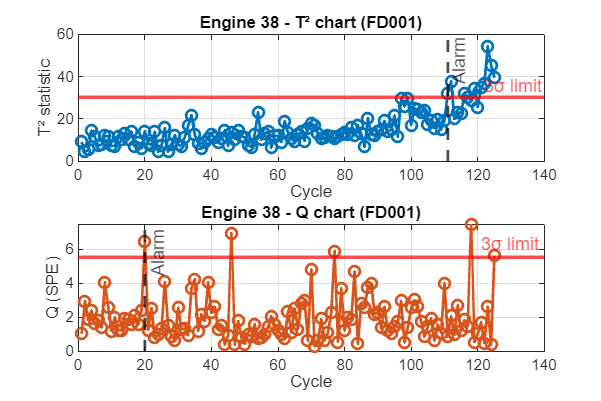

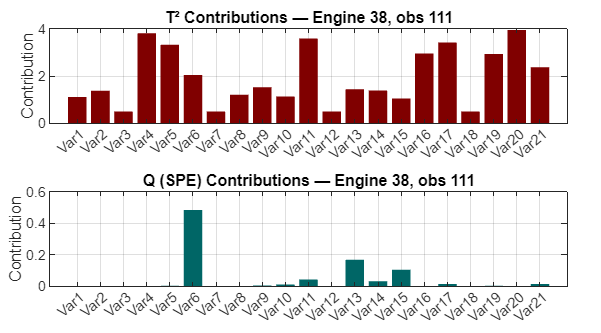

Engine 95 (FD001): 

T² alarm → lead time = 55

Q alarm → lead time = 19

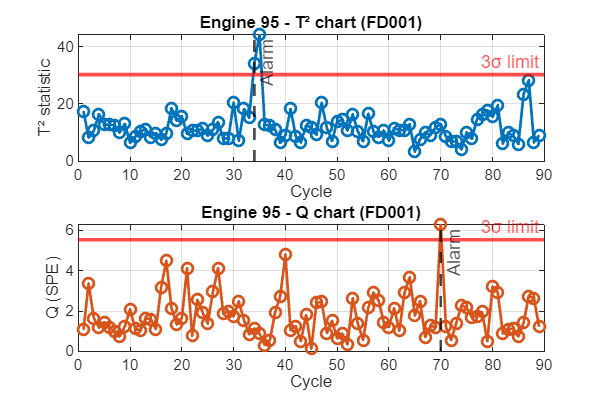

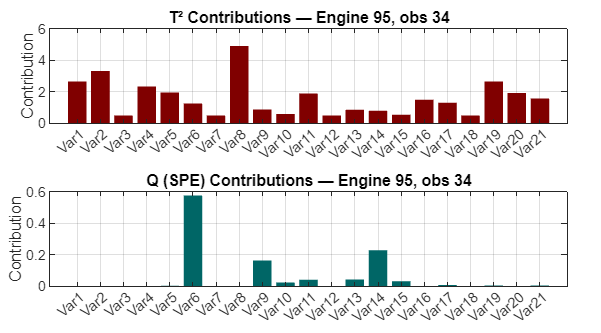

Engine 72 (FD001): 

T² alarm → lead time = 114

Q alarm → lead time = 127

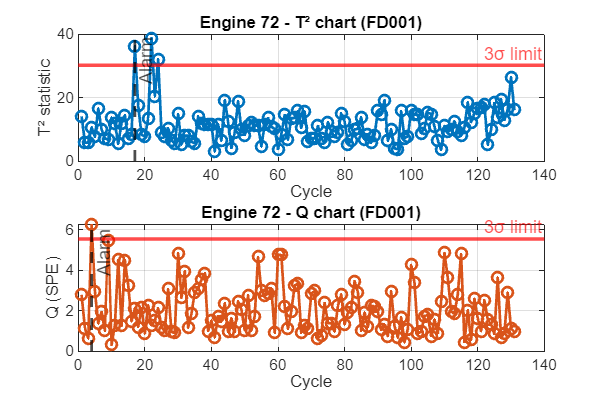

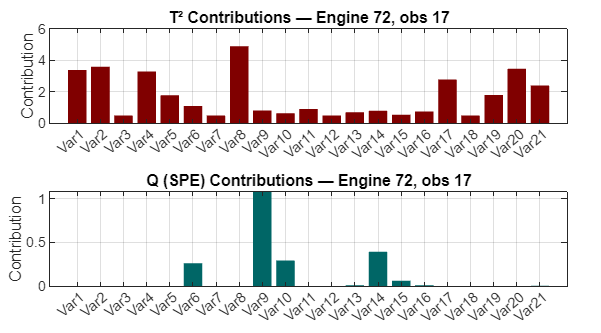

Engine 59 (FD001): 

T² alarm → lead time = 81

Q alarm → lead time = 40

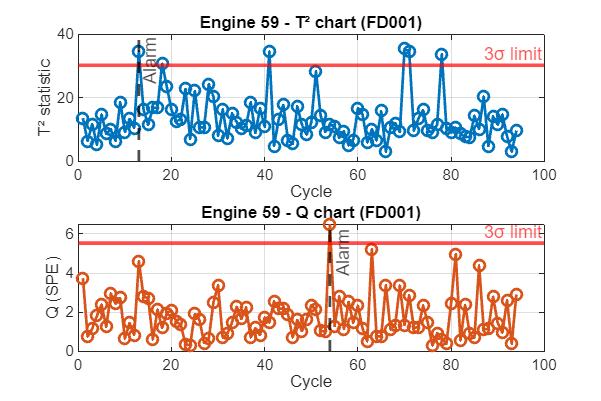

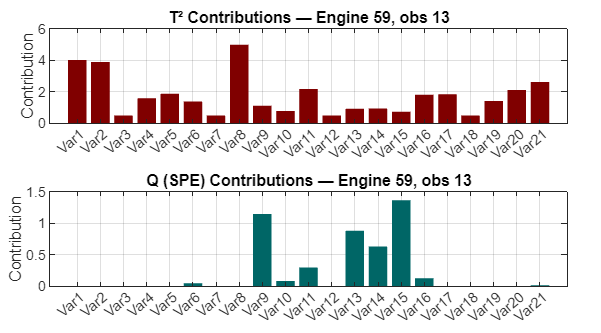

Engine 15 (FD001): 

T² alarm → lead time = 46

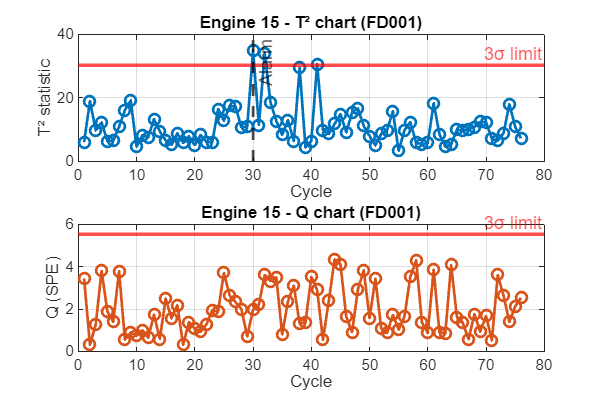

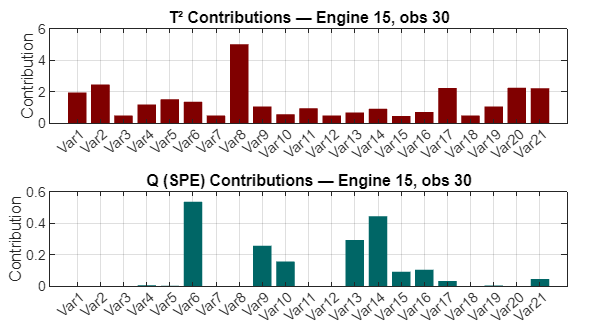

Engine 96 (FD001): 

T² alarm → lead time = 94

Q alarm → lead time = 55

Engine 6 (FD001): 

T² alarm → lead time = 43

Engine 81 (FD001): 

T² alarm → lead time = 151

Q alarm → lead time = 92

Engine 56 (FD001): 

T² alarm → lead time = 22

Q alarm → lead time = 113

Engine 65 (FD001): 

T² alarm → lead time = 59

Q alarm → lead time = 34

Engine 2 (FD001): 

Q alarm → lead time = 35

Engine 87 (FD001): 

T² alarm → lead time = 55

Engine 74 (FD001): 

Q alarm → lead time = 115

Engine 19 (FD001): 

T² alarm → lead time = 130

Q alarm → lead time = 72

Engine 16 (FD001): 

T² alarm → lead time = 62

Engine 86 (FD001): 

no alarm T² or Q.


Engine 26 (FD001): 

T² alarm → lead time = 39

Q alarm → lead time = 1

Engine 44 (FD001): 

T² alarm → lead time = 35

Q alarm → lead time = 20

Engine 36 (FD001): 

T² alarm → lead time = 36

Q alarm → lead time = 72

Engine 24 (FD001): 

T² alarm → lead time = 181

Q alarm → lead time = 143


==================== Dataset: FD002 ====================


Engine 98 (FD002): 

no alarm T² or Q.


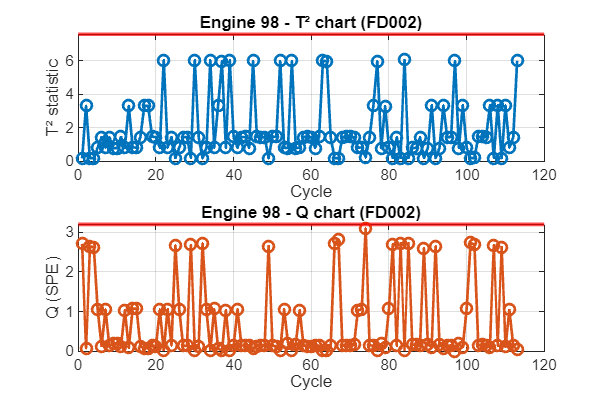

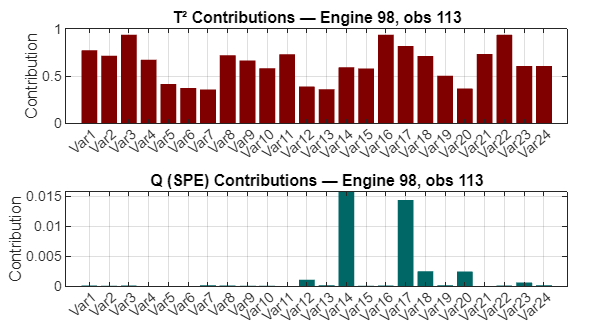

Engine 246 (FD002): 

no alarm T² or Q.


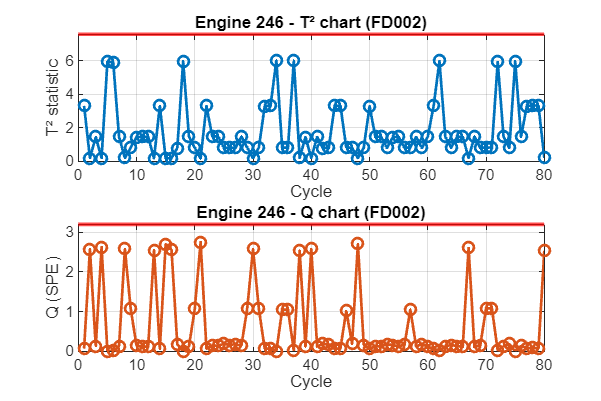

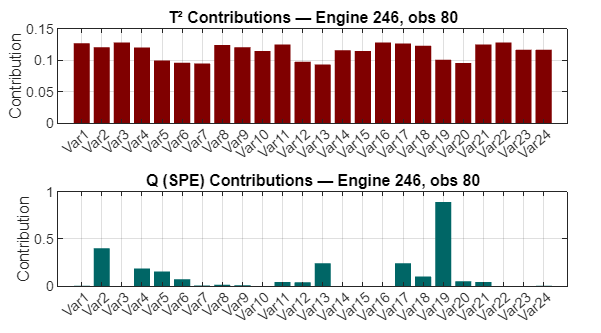

Engine 189 (FD002): 

no alarm T² or Q.


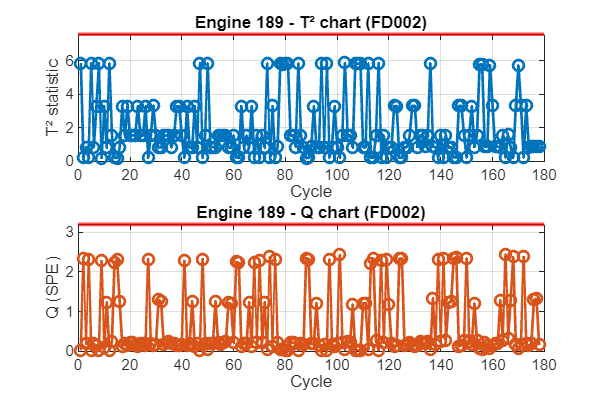

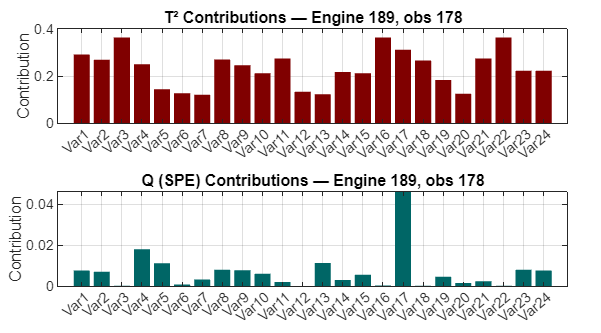

Engine 154 (FD002): 

no alarm T² or Q.


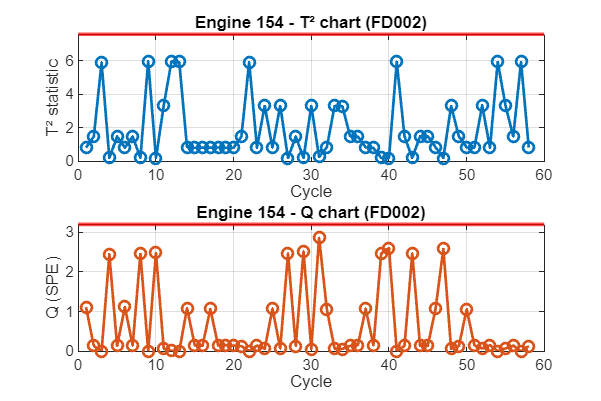

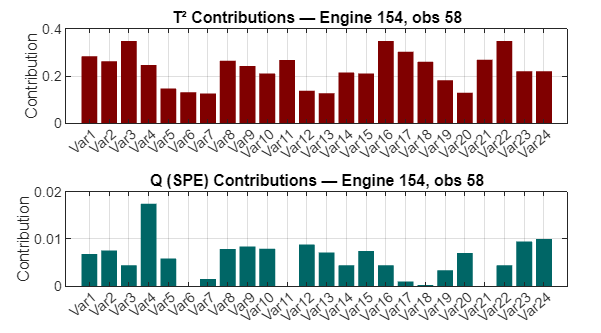

Engine 40 (FD002): 

no alarm T² or Q.


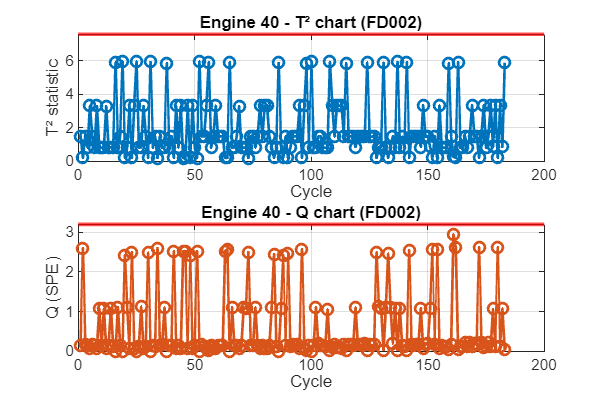

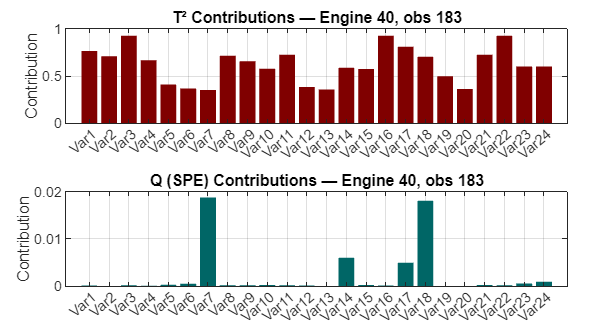

Engine 255 (FD002): 

no alarm T² or Q.


Engine 15 (FD002): 

no alarm T² or Q.


Engine 219 (FD002): 

no alarm T² or Q.


Engine 151 (FD002): 

no alarm T² or Q.


Engine 178 (FD002): 

no alarm T² or Q.


Engine 6 (FD002): 

no alarm T² or Q.


Engine 241 (FD002): 

no alarm T² or Q.


Engine 206 (FD002): 

no alarm T² or Q.


Engine 53 (FD002): 

no alarm T² or Q.


Engine 45 (FD002): 

no alarm T² or Q.


Engine 245 (FD002): 

no alarm T² or Q.


Engine 74 (FD002): 

no alarm T² or Q.


Engine 127 (FD002): 

no alarm T² or Q.


Engine 105 (FD002): 

no alarm T² or Q.


Engine 70 (FD002): 

no alarm T² or Q.


Engine 147 (FD002): 

no alarm T² or Q.


Engine 34 (FD002): 

no alarm T² or Q.


Engine 240 (FD002): 

no alarm T² or Q.


Engine 87 (FD002): 

no alarm T² or Q.


Engine 108 (FD002): 

no alarm T² or Q.


Engine 184 (FD002): 

no alarm T² or Q.


Engine 47 (FD002): 

no alarm T² or Q.


Engine 120 (FD002): 

no alarm T² or Q.


Engine 137 (FD002): 

no alarm T² or Q.


Engine 11 (FD002): 

no alarm T² or Q.


Engine 140 (FD002): 

no alarm T² or Q.


Engine 39 (FD002): 

no alarm T² or Q.


Engine 253 (FD002): 

no alarm T² or Q.


Engine 215 (FD002): 

no alarm T² or Q.


Engine 218 (FD002): 

no alarm T² or Q.


Engine 182 (FD002): 

Q alarm → lead time = 9

Engine 68 (FD002): 

no alarm T² or Q.


Engine 22 (FD002): 

no alarm T² or Q.


Engine 152 (FD002): 

no alarm T² or Q.


Engine 97 (FD002): 

no alarm T² or Q.


Engine 27 (FD002): 

no alarm T² or Q.


Engine 235 (FD002): 

no alarm T² or Q.


Engine 8 (FD002): 

no alarm T² or Q.


Engine 197 (FD002): 

no alarm T² or Q.


Engine 56 (FD002): 

no alarm T² or Q.


Engine 142 (FD002): 

no alarm T² or Q.


Engine 67 (FD002): 

no alarm T² or Q.


Engine 111 (FD002): 

Q alarm → lead time = 6

Engine 116 (FD002): 

Q alarm → lead time = 11

Engine 228 (FD002): 

no alarm T² or Q.


Engine 203 (FD002): 

no alarm T² or Q.


Engine 162 (FD002): 

no alarm T² or Q.



==================== Dataset: FD003 ====================


Engine 38 (FD003): 

Q alarm → lead time = 118

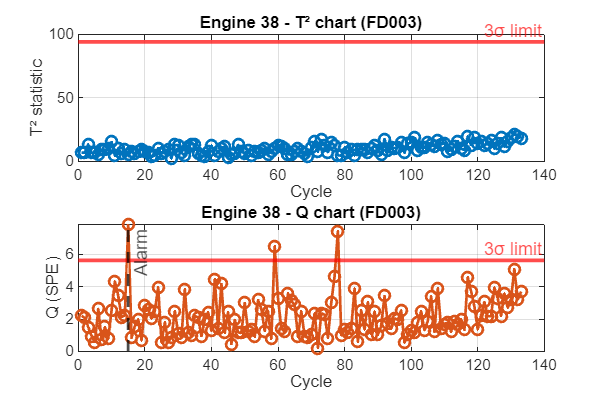

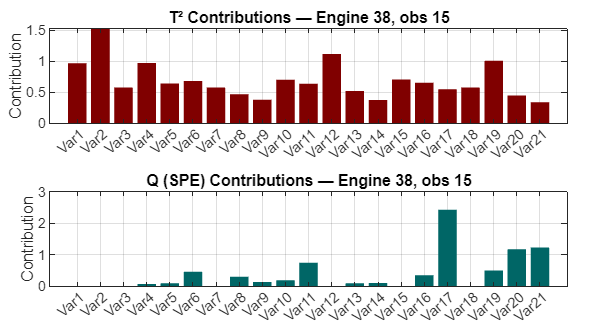

Engine 95 (FD003): 

Q alarm → lead time = 110

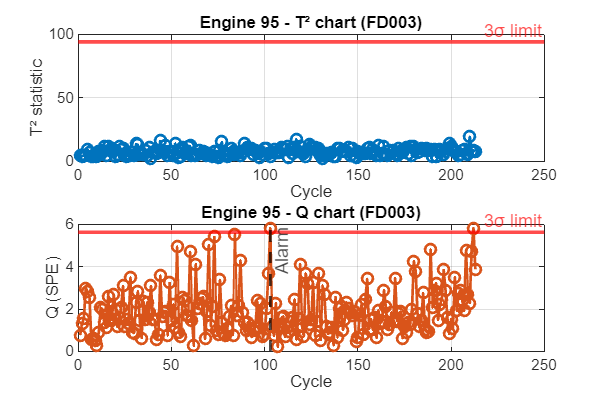

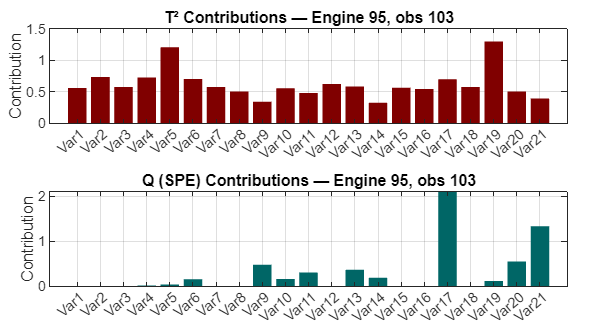

Engine 72 (FD003): 

T² alarm → lead time = 13

Q alarm → lead time = 206

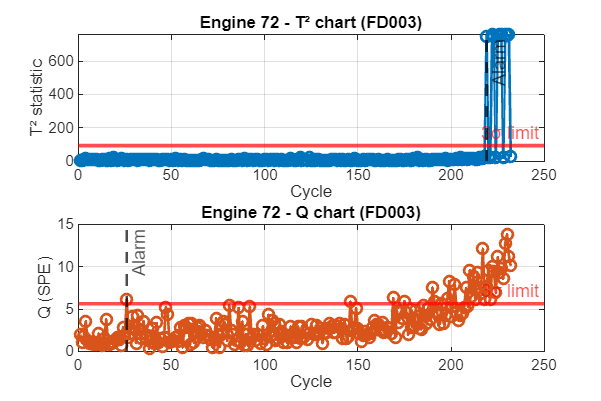

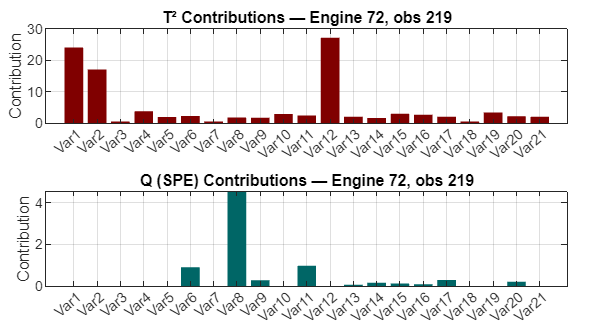

Engine 59 (FD003): 

Q alarm → lead time = 135

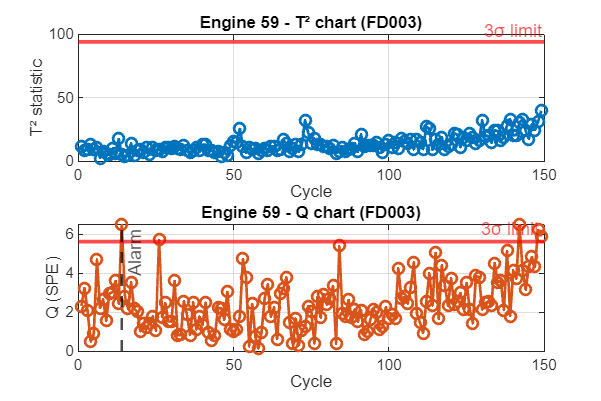

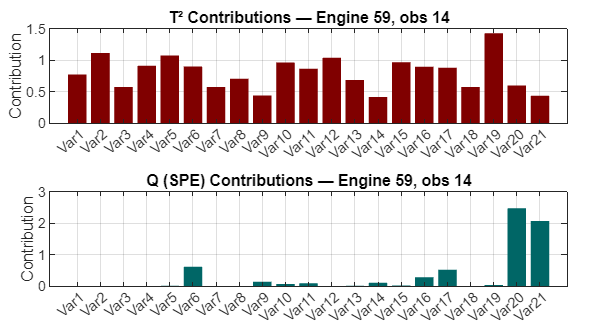

Engine 15 (FD003): 

Q alarm → lead time = 30

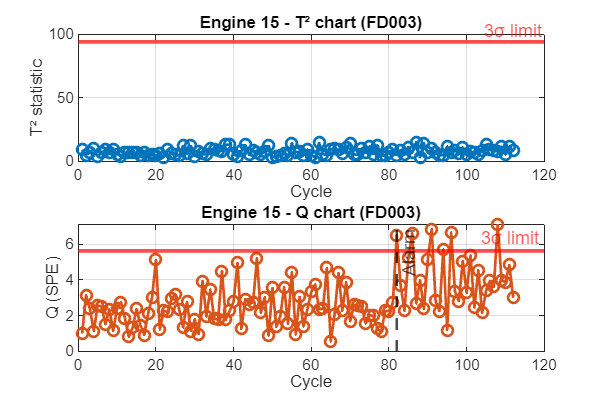

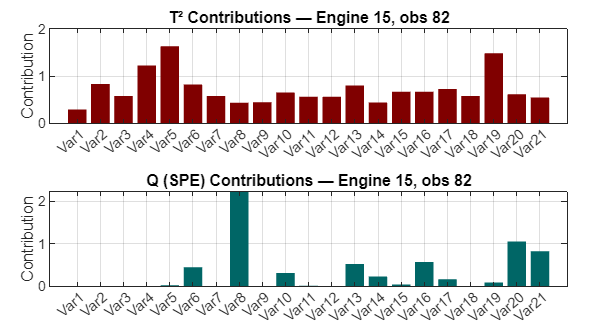

Engine 96 (FD003): 

T² alarm → lead time = 251

Q alarm → lead time = 309

Engine 6 (FD003): 

no alarm T² or Q.


Engine 81 (FD003): 

T² alarm → lead time = 20

Q alarm → lead time = 117

Engine 56 (FD003): 

Q alarm → lead time = 91

Engine 65 (FD003): 

Q alarm → lead time = 49

Engine 2 (FD003): 

no alarm T² or Q.


Engine 87 (FD003): 

Q alarm → lead time = 206

Engine 74 (FD003): 

Q alarm → lead time = 53

Engine 19 (FD003): 

Q alarm → lead time = 90

Engine 16 (FD003): 

T² alarm → lead time = 124

Q alarm → lead time = 118

Engine 86 (FD003): 

T² alarm → lead time = 1

Q alarm → lead time = 75

Engine 26 (FD003): 

Q alarm → lead time = 28

Engine 44 (FD003): 

Q alarm → lead time = 78

Engine 36 (FD003): 

no alarm T² or Q.


Engine 24 (FD003): 

T² alarm → lead time = 98

Q alarm → lead time = 474


==================== Dataset: FD004 ====================


Engine 93 (FD004): 

no alarm T² or Q.


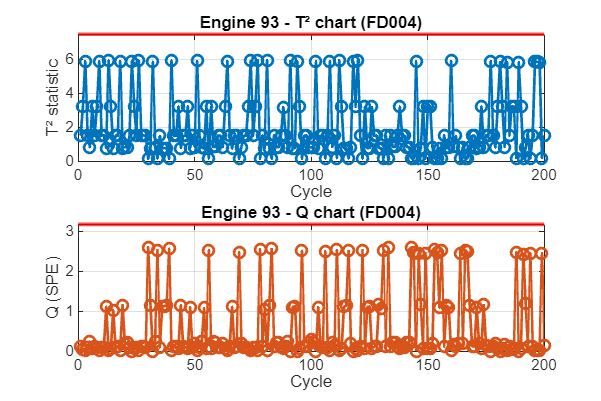

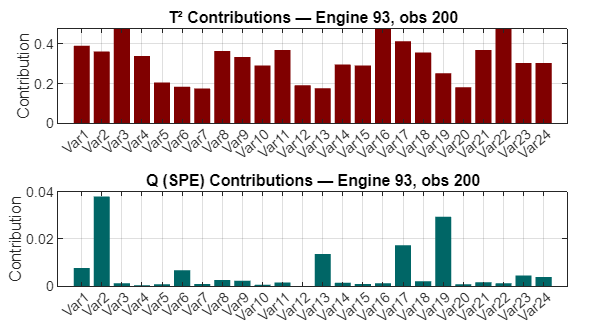

Engine 235 (FD004): 

no alarm T² or Q.


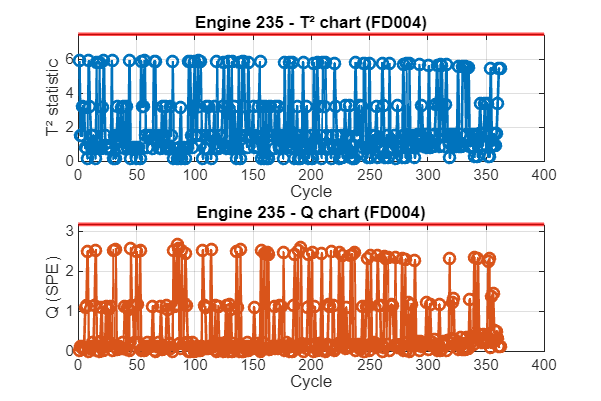

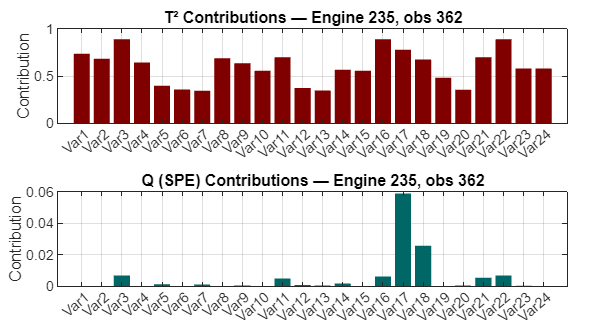

Engine 181 (FD004): 

no alarm T² or Q.


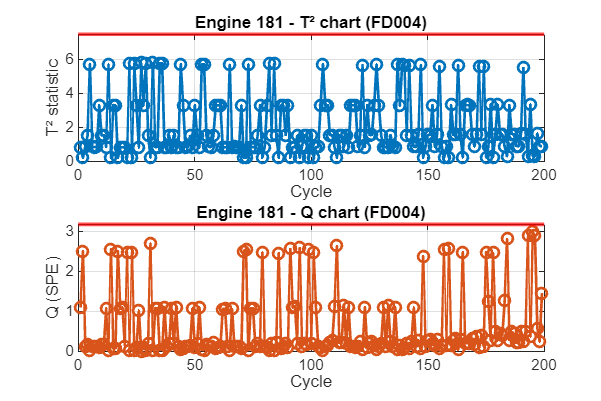

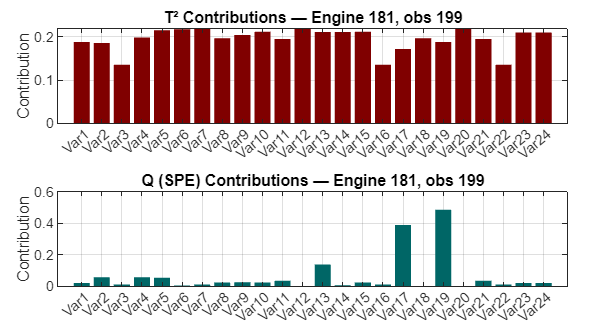

Engine 147 (FD004): 

no alarm T² or Q.


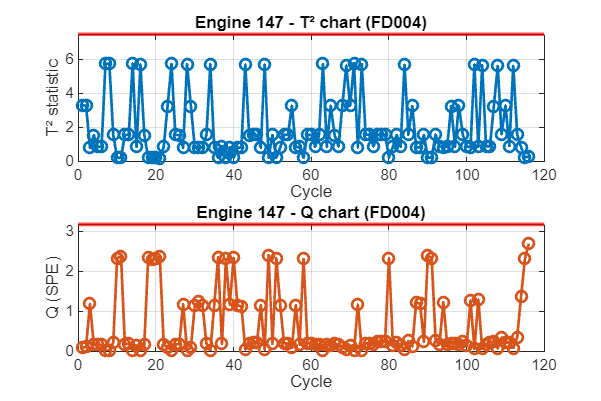

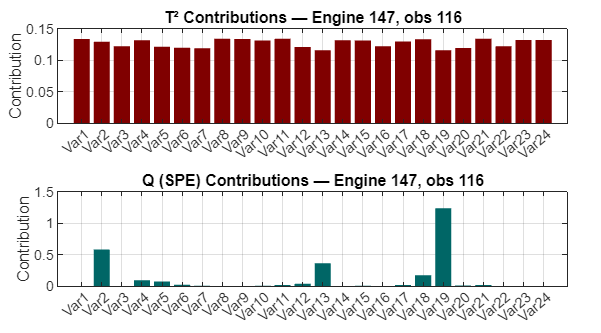

Engine 39 (FD004): 

no alarm T² or Q.


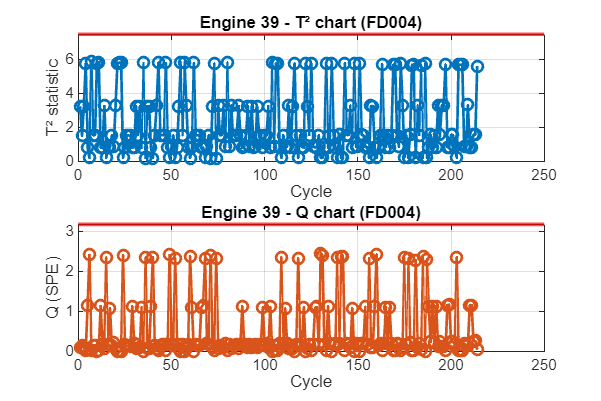

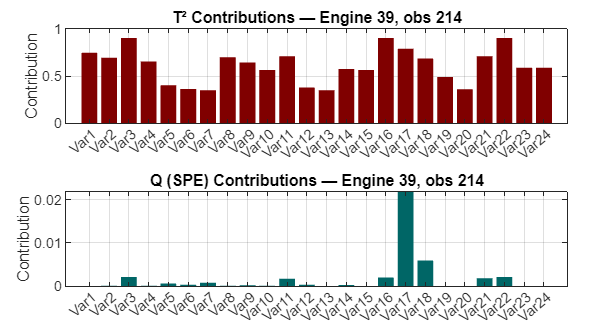

Engine 38 (FD004): 

Q alarm → lead time = 8

Engine 15 (FD004): 

no alarm T² or Q.


Engine 209 (FD004): 

no alarm T² or Q.


Engine 145 (FD004): 

no alarm T² or Q.


Engine 170 (FD004): 

no alarm T² or Q.


Engine 5 (FD004): 

no alarm T² or Q.


Engine 230 (FD004): 

no alarm T² or Q.


Engine 197 (FD004): 

no alarm T² or Q.


Engine 50 (FD004): 

no alarm T² or Q.


Engine 43 (FD004): 

no alarm T² or Q.


Engine 234 (FD004): 

no alarm T² or Q.


Engine 71 (FD004): 

no alarm T² or Q.


Engine 122 (FD004): 

no alarm T² or Q.


Engine 100 (FD004): 

no alarm T² or Q.


Engine 67 (FD004): 

no alarm T² or Q.


Engine 140 (FD004): 

no alarm T² or Q.


Engine 32 (FD004): 

Q alarm → lead time = 19

Engine 229 (FD004): 

no alarm T² or Q.


Engine 83 (FD004): 

no alarm T² or Q.


Engine 103 (FD004): 

no alarm T² or Q.


Engine 176 (FD004): 

no alarm T² or Q.


Engine 45 (FD004): 

no alarm T² or Q.


Engine 114 (FD004): 

no alarm T² or Q.


Engine 131 (FD004): 

no alarm T² or Q.


Engine 11 (FD004): 

no alarm T² or Q.


Engine 133 (FD004): 

no alarm T² or Q.


Engine 243 (FD004): 

no alarm T² or Q.


Engine 242 (FD004): 

no alarm T² or Q.


Engine 205 (FD004): 

no alarm T² or Q.


Engine 207 (FD004): 

no alarm T² or Q.


Engine 173 (FD004): 

Q alarm → lead time = 19

Engine 65 (FD004): 

no alarm T² or Q.


Engine 21 (FD004): 

no alarm T² or Q.


Engine 144 (FD004): 

no alarm T² or Q.


Engine 92 (FD004): 

no alarm T² or Q.


Engine 26 (FD004): 

no alarm T² or Q.


Engine 224 (FD004): 

no alarm T² or Q.


Engine 8 (FD004): 

no alarm T² or Q.


Engine 187 (FD004): 

no alarm T² or Q.


Engine 53 (FD004): 

no alarm T² or Q.


Engine 135 (FD004): 

no alarm T² or Q.


Engine 63 (FD004): 

no alarm T² or Q.


Engine 105 (FD004): 

no alarm T² or Q.


Engine 110 (FD004): 

no alarm T² or Q.


Engine 37 (FD004): 

no alarm T² or Q.


for f = 1:4
    fprintf('\n==================== Dataset: %s ====================\n', dataset_names{f});
    trainData = trainSets{f};
    testData  = testSets{f};
    unit_train  = trainData(:,1);
    cycle_train = trainData(:,2);
    X_train     = trainData(:,3:end);
    X_test_all  = testData(:,3:end);

    varPerCol = var(X_train);
    constVars = find(varPerCol == 0);
    if ~isempty(constVars)
        X_train(:,constVars) = [];
        X_test_all(:,constVars) = [];
    end
    nVar = size(X_train,2);
    varNames = arrayfun(@(x) sprintf('Var%d',x), 1:nVar, 'UniformOutput', false);

    % Healthy Data (first 30% of cycles for each engine)
    uniqueUnits = unique(unit_train);
    healthy_data_indices = [];
    for i = 1:numel(uniqueUnits)
        unit_id = uniqueUnits(i);
        unit_indices = find(unit_train==unit_id);
        max_cycle = max(cycle_train(unit_indices));
        healthy_unit_indices = unit_indices(cycle_train(unit_indices) <= floor(0.30*max_cycle));
        healthy_data_indices = [healthy_data_indices; healthy_unit_indices];
    end
    X_healthy = X_train(healthy_data_indices,:);

    % PCA model
    mu = mean(X_healthy);
    sig = std(X_healthy);
    Xh_scaled = (X_healthy - mu)./sig;

    [coeff, ~, latent, ~, explained] = pca(Xh_scaled,'Centered',false);
    cumExplained = cumsum(explained);
    k = find(cumExplained>=90,1); if isempty(k), k=size(coeff,2); end
    coeff_k = coeff(:,1:k);
    latent_k = latent(1:k);

    % Control limits from healthy data
    T2_h = t2comp(Xh_scaled, coeff_k, latent_k);
    Q_h  = qcomp(Xh_scaled, coeff_k);
    alarm_T2 = mean(T2_h) + 3*std(T2_h);
    alarm_Q  = mean(Q_h)  + 3*std(Q_h);

    % Test phase: select random subset of engines 
    test_units_all = unique(testData(:,1));
    nTestUnits = round(0.2 * numel(test_units_all));
    rng(42);
    test_units = test_units_all(randperm(numel(test_units_all), nTestUnits));

    plot_sample = test_units(1:min(5,numel(test_units)));

    for u = 1:numel(test_units)
        test_id = test_units(u);
        idx_test = find(testData(:,1) == test_id);
        X_test_engine = X_test_all(idx_test,:);
        N_test = size(X_test_engine,1);
        X_test_scaled = (X_test_engine - mu) ./ sig;
        T2_test = t2comp(X_test_scaled, coeff_k, latent_k);
        Q_test  = qcomp(X_test_scaled, coeff_k);

        % Find first alarms 
        alarm_idx_T2 = find(T2_test > alarm_T2, 1);
        alarm_idx_Q  = find(Q_test  > alarm_Q,  1);

        % Lead time calculation
        last_cycle = N_test;
        leadtime_T2 = NaN; leadtime_Q = NaN;
        if ~isempty(alarm_idx_T2), leadtime_T2 = last_cycle - alarm_idx_T2; end
        if ~isempty(alarm_idx_Q),  leadtime_Q  = last_cycle - alarm_idx_Q;  end

        fprintf('Engine %d (%s): ', test_id, dataset_names{f});
        if ~isnan(leadtime_T2) || ~isnan(leadtime_Q)
            if ~isnan(leadtime_T2)
                fprintf('T² alarm → lead time = %d', leadtime_T2);
            end
            if ~isnan(leadtime_Q)
                if ~isnan(leadtime_T2); end
                fprintf('Q alarm → lead time = %d', leadtime_Q);
            end
            fprintf('\n');
        else
            fprintf('no alarm T² or Q.\n');
        end

        % Plot charts only for selected engines
        if ismember(test_id, plot_sample)
            figure('Color','w','Position',[100 100 900 600]);

            subplot(2,1,1);
            plot(1:N_test, T2_test,'-o','LineWidth',1.5,'Color',[0 0.45 0.74]); hold on;
            yline(alarm_T2,'-r','3σ limit','LineWidth',2);
            if ~isempty(alarm_idx_T2), xline(alarm_idx_T2,'--k','Alarm','LineWidth',1.5); end
            xlabel('Cycle'); ylabel('T² statistic');
            title(sprintf('Engine %d - T² chart (%s)', test_id, dataset_names{f}));
            grid on;

            subplot(2,1,2);
            plot(1:N_test, Q_test,'-o','LineWidth',1.5,'Color',[0.85 0.33 0.1]); hold on;
            yline(alarm_Q,'-r','3σ limit','LineWidth',2);
            if ~isempty(alarm_idx_Q), xline(alarm_idx_Q,'--k','Alarm','LineWidth',1.5); end
            xlabel('Cycle'); ylabel('Q (SPE)');
            title(sprintf('Engine %d - Q chart (%s)', test_id, dataset_names{f}));
            grid on;

            % Variable contributions at alarm point
            if ~isempty(alarm_idx_T2)
                idxObs = alarm_idx_T2;
            elseif ~isempty(alarm_idx_Q)
                idxObs = alarm_idx_Q;
            else
                idxObs = N_test;
            end

            xrow = X_test_scaled(idxObs,:);
            T2_contrib = t2contr(xrow, coeff_k, latent_k, k);
            Q_contrib  = qcontr(xrow, coeff_k, k);

            figure('Color','w','Position',[100 100 900 500]);
            tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

            nexttile;
            bar(T2_contrib,'FaceColor',[0.50 0 0],'EdgeColor','none');
            title(sprintf('T² Contributions — Engine %d, obs %d', test_id, idxObs));
            ylabel('Contribution'); xticks(1:numel(varNames)); xticklabels(varNames); xtickangle(40);
            grid on; box on;

            nexttile;
            bar(Q_contrib,'FaceColor',[0 0.40 0.40],'EdgeColor','none');
            title(sprintf('Q (SPE) Contributions — Engine %d, obs %d', test_id, idxObs));
            ylabel('Contribution'); xticks(1:numel(varNames)); xticklabels(varNames); xtickangle(40);
            grid on; box on;
        end
    end
end